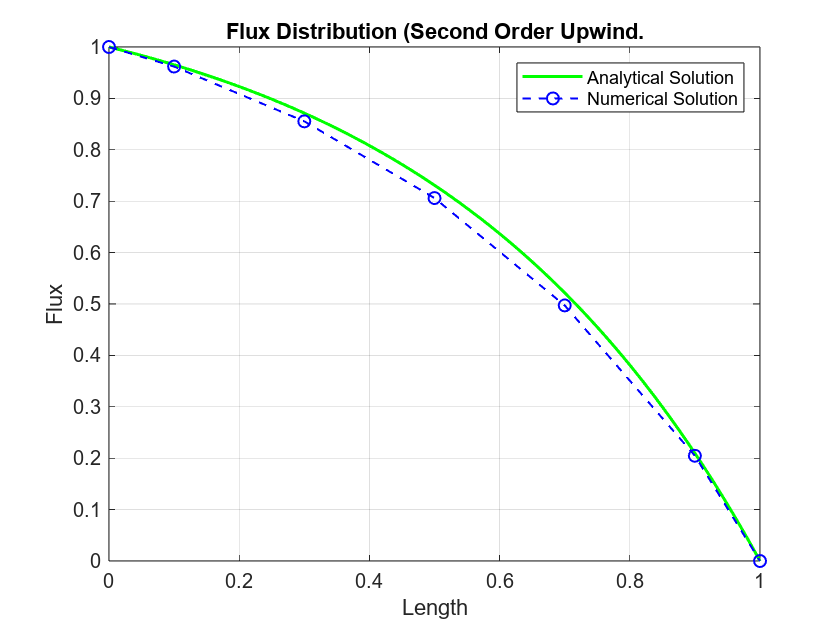

%% Second Order Upwind Scheme for Convection-Diffusion Problem
% This code solves the one-dimensional steady-state convection-diffusion
% equation using the second-order upwind scheme.
n = 5; % Number of control volumes
L = 1; % Total length
gamma = 0.1; % Diffusion coefficient
v_in = 0.2; % Inlet velocity
phi1 = 1; % Boundary condition at left face
phi0 = 0; % Boundary condition at right face
rho = 1; % Density
guess = 1; % Initial guess for phi
P = rho*v_in/(gamma/L);
[x,phi_N]=SecondOrderUpwind(L, gamma, v_in, phi1, phi0, rho, n);   

x_plot = linspace(0, L, 100);
  
phi_analytical = @(x) phi1 + (phi0 - phi1) * ((exp(P * x / L) - 1) / (exp(P) - 1));
phi_plot = phi_analytical(x_plot);

   figure;
   plot(x_plot, phi_plot, 'g', 'LineWidth', 1.5);
   hold on;
   plot(x, phi_N, 'bo--', 'LineWidth', 1);
   xlabel('Length');
   ylabel('Flux');
   title('Flux Distribution (Second Order Upwind.');
   grid on;
   legend('Analytical Solution', 'Numerical Solution ');

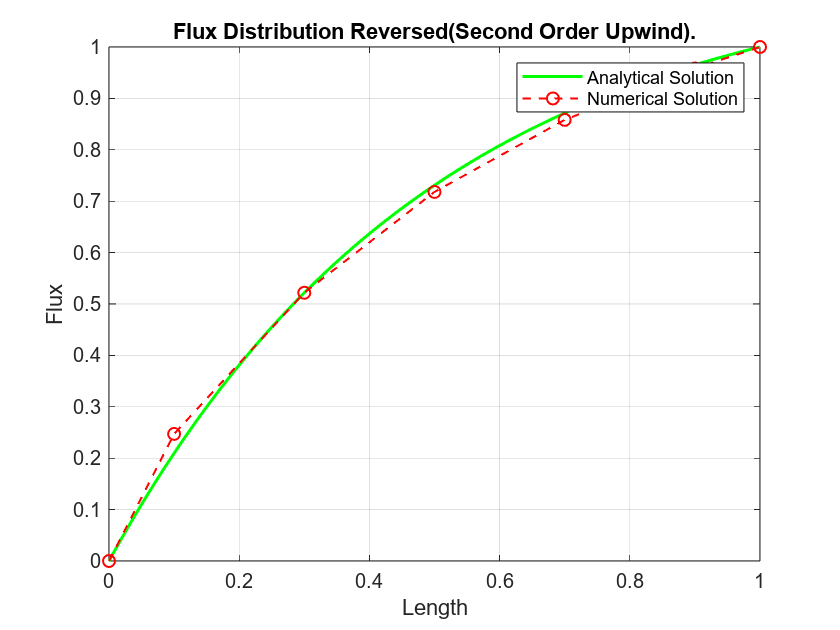

   [x,phi_NR]=SecondOrderUpwind(L, gamma, -v_in, phi0, phi1, rho, n);   

x_plot = linspace(0, L, 100);
  
phi_analytical = @(x) phi1 + (phi0 - phi1) * ((exp(P * x / L) - 1) / (exp(P) - 1));
phi_plot = flip(phi_analytical(x_plot)); 

   figure;
   plot(x_plot, phi_plot, 'g', 'LineWidth', 1.5);
   hold on;
   plot(x, phi_NR, 'ro--', 'LineWidth', 1);
   xlabel('Length');
   ylabel('Flux');
   title('Flux Distribution Reversed(Second Order Upwind).');
   grid on;
   legend('Analytical Solution', 'Numerical Solution ');

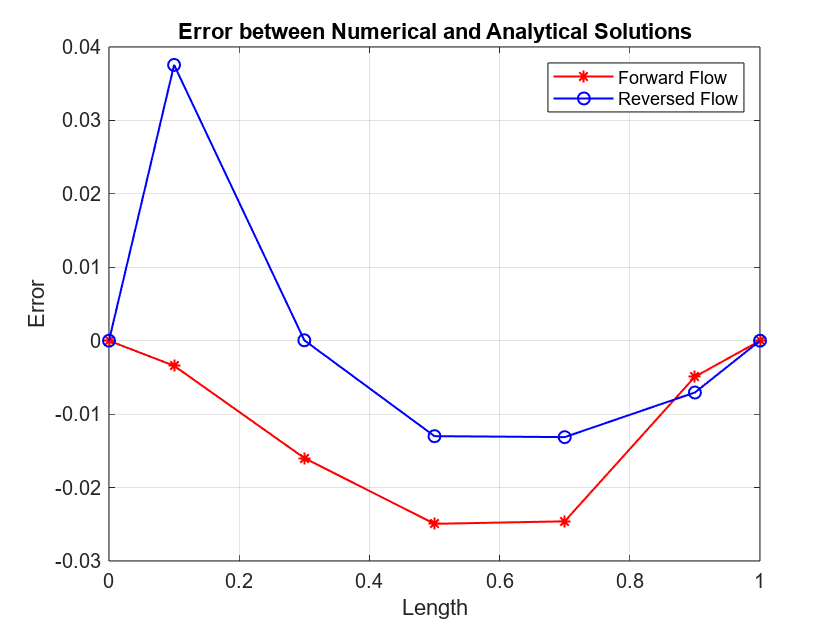

phi_analytical_interior = phi_analytical(x(1:end));
error_forward = phi_N(1:end) - phi_analytical_interior;
error_reversed = phi_NR(1:end) - flip(phi_analytical_interior);

figure;
plot(x(1:end), error_forward, 'r*-', LineWidth=1);
hold on;
plot(x(1:end), error_reversed, 'bo-', LineWidth=1);
xlabel('Length');
ylabel('Error');
title('Error between Numerical and Analytical Solutions');
legend('Forward Flow', 'Reversed Flow');
grid on;
hold off;

error = sqrt(sum((phi_N(1:end) - phi_analytical_interior).^2) / n);
disp(['Normalised Error: ', num2str(error), '%']);

Normalised Error: 0.017423%


function[x,phi_N]= SecondOrderUpwind(L, gamma, v_in, phi1, phi0, rho, n)

   % Calculate the step size
   dx = L/n;

   % Initialize arrays for spatial coordinates and coefficients
   x = zeros(1, n+2);
   dxw = zeros(1, n+2);
   dxe = zeros(1, n+2);
   phi_N = zeros(1, n+2);
   Fw = zeros(1, n+2);
   Fe = zeros(1, n+2);
   Dw = zeros(1, n+2);
   De = zeros(1, n+2);

   % Calculate Peclet number
   Pe = rho * v_in / (gamma / dx);
   P = rho * v_in / (gamma / L);

   % Set up spatial coordinates and distances
   x(1) = 0;
   x(2) = dx / 2;
   for i = 3:n+1
       x(i) = x(i-1) + dx;
   end
   x(n+2) = L;

   for i = 2:n+1
       dxw(i) = (x(i) - x(i-1));
       dxe(i) = (x(i+1) - x(i));
       Fe(i) = rho * v_in;
       Fw(i) = rho * v_in;
       De(i) = gamma / dxe(i);
       Dw(i) = gamma / dxw(i);
   end

   % Initialize coefficient matrices
   aw = zeros(1, n+2);
   ae = zeros(1, n+2);
   ap = zeros(1, n+2);
   d = zeros(1, n+2);
   a = zeros(1, n+2);
   b = zeros(1, n+2);
   c = zeros(1, n+2);
   dnew = zeros(1, n+2);
   cnew = zeros(1, n+2);
   Pe = rho*v_in/(gamma/dx); 
   

   % Calculate coefficients
   for i = 3:n+1
       aw(i) = Dw(i) + max(0, 0.5 * (Fw(i) + Fe(i)));
       ae(i) = De(i) + max(0, 0.5 * (-Fw(i) - Fe(i)));
       ap(i) = aw(i) + ae(i) + Fe(i) - Fw(i);
   end

   aw(2) = Dw(2) + max(0, (Fw(2) + Fe(2)));
   ae(2) = De(2) + max(0, (-Fw(2) - Fe(2)));

   for i = 2:n+1
       ap(i) = aw(i) + ae(i) + Fe(i) - Fw(i);
       a(i) = -ae(i);
       b(i) = -aw(i);
       d(i) = ap(i);
   end

   % Apply boundary conditions
   d(1) = 1;
   b(1) = 0;
   a(1) = 0;
   c(1) = phi1;
   d(n+2) = 1;
   b(n+2) = 0;
   a(n+2) = 0;
   c(n+2) = phi0;

   % Perform TDMA algorithm
   dnew(1) = d(1);
   cnew(1) = c(1);
   for i = 2:n+2
       dnew(i) = d(i) - b(i) * a(i-1) / dnew(i-1);
       cnew(i) = c(i) - b(i) * cnew(i-1) / dnew(i-1);
   end
   phi_N(n+2) = cnew(n+2) / dnew(n+2);
   for i = n+1:-1:1
       phi_N(i) = (cnew(i) - a(i) * phi_N(i+1)) / dnew(i);
   end

  end


